# Integration by Parts

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Integration by parts is an extremely powerful method of integration that will only come into full focus once you apply it to solving differential equations. For the moment, however, it will allow you to solve some integrals that substitution is no help with. 

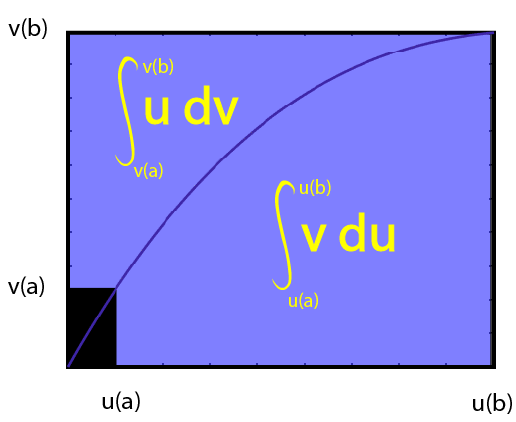

Integration by parts allows you to subdivide your integrand into integrated and differentiated components and recombine those pieces in ways that can be easier to compute.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

## Identifying integrable and differentiable components

When there is a natural logarithm in an integrand that doesn't exist as part of a substitution, the only exact method available is to use integration by parts with the natural logarithm as $u$ in the equation 


$$\int u(t)\cdot \frac{dv}{dt}\; dt = u(t)\cdot v(t) - \int v(t) \frac{du}{dt}\; dt. \;\;\;\;\;\;\; (\diamond)$$


  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

### Powers and Logarithms Practice

**Solution: **Answers vary. Sample solution:

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declare symbolic variables
    varOpts = [t r x z];                 % Define the list of variables to use in the problems
end
[myFun1,varChoice] = GenProbType(varOpts,3);  % genProbType is defined in Helper Functions
% genProbType sets up a variable and generates a randomized function

                                   % Run this section

if ~exist("myFun1","var")
    disp("You must generate a power and logarithms practice problem before you can solve it.")
else
    myAnswer = -3/(2*t^2)*log(3*t)-3/(4*t^2)+C;     % User-defined solution, default value r
    assume(varChoice>0)
    Check1(myFun1,varChoice,myAnswer);
end
                          % Run this section

### Polynomials and Cosines, Sines or Exponentials Practice

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declare symbolic variables
    varOpts = [t r x z];                 % Define the list of variables to use in the problems
end
    [myFun2,varChoice] = GenProbType(varOpts,2);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    
                                   % Run this section

if ~exist("myFun2","var")
    disp("You must generate a polynomials and cosines, sines or exponentials practice problem before you can solve it.")
else
    myAnswer = (x^3/3-2*x/9)*cos(3*x-3)+(2/27-x^2/3)*sin(3*x-3)+C;     % User-defined solution, default value r
    assume(varChoice>0)
    Check1(myFun2,varChoice,myAnswer);
end
                          % Run this section

### Cosines, Sines, and Exponentials Practice

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declare symbolic variables
    varOpts = [t r x z];                 % Define the list of variables to use in the problems
end
    [myFun3,varChoice] = GenProbType(varOpts,4);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    
                                   % Run this section

if ~exist("myFun3","var")
    disp("You must generate a cosines, sines, and exponentials practice problem before you can solve it.")
else
    myAnswer = 2*exp(-r-3)*(sin(3*r+1)/3-cos(3*r+1)/9)*9/10+C;     % User-defined solution, default value r
    assume(varChoice>0)
    Check1(myFun3,varChoice,myAnswer);
end
                          % Run this section

## Practice Randomized Integration by Parts Integrals

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

**Solution: **Answers vary

### Practice App

You can practice in the Calculus Flashcards app. You can start the app by clicking on the image below. You should set the problem type to be "Integration by Parts" in the Integrals section. The app will open in a new window.

[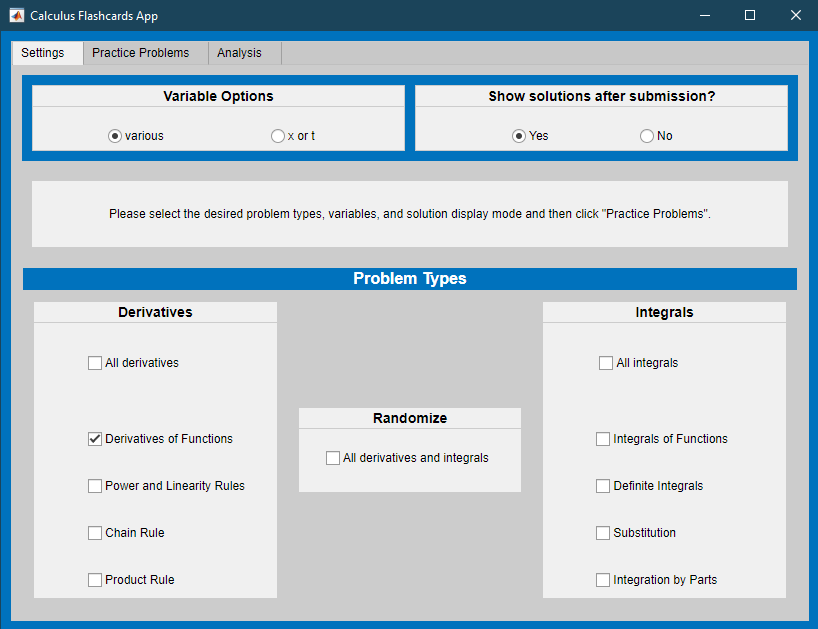](matlab: CalculusFlashcards)

 
run("CalculusFlashcards.mlapp")

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

**Generate randomized functions for integral practice**

Generate randomized functions

function [myFunc,type] = GenFunDiff(bds,var,range)
syms f(t)                    % Create a symbolic function f(t)
params = randi(bds,[1 4]);   % Randomly choose parameter values
shift = randi([0 max(abs(bds))],1); % Randomly choose a shift that may be 0
sgns = randi([0 1],[1 3]);   % Randomly choose +/- signs
type = randi(range,1);


% For readability, create parameters a,b,c, and d
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, it is only used as a denominator
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^c*sin(b*t+d);
    case 2
        f(t) = a*t^c*cos(b*t+d);
    case 3
        f(t) = a*t^c*exp(b*t+d);
    case 4
        f(t) = a*t^b*log(c*t);
    case 5 
        f(t) = sin(b*t+d)*cos(c*t+a);
    case 6
        f(t) = a*sin(b*t+d)*exp(b/c*t+c*d);
    case 7
        f(t) = a*cos(b*t+d)*exp(b/c*t+c*d);
end
myFunc = f(var);
end

Print the problem that has been created

function [myFun,varChoice] = GenProbType(varOpts,probType)
% genProbType sets up a variable and generates a randomized function
%
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required

% Randomly select a variable from the set varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Use genFunDiff to generate simple functions
% genFunDiff is defined in Helper Functions
% The inputs to genFunDiff are the variable varChoice, a range of values
% from which to select coefficients and a value indicating which warnings
% have already been printed during problem generation
syms f(x) x
switch probType
    case 1 % By parts derivative, general
        [f(x),~] = GenFunDiff([1 3],x,[1 7]);
    case 2 % By parts, poly * cos/sin/exp
        [f(x),~] = GenFunDiff([1 3],x,[1 3]);
    case 3 % By parts, poly * log
        [f(x),~] = GenFunDiff([1 3],x,[4 4]);
    case 4 % By parts, cos/sin * cos/sin/exp
        [f(x),~] = GenFunDiff([1 3],x,[5 7]);
end
myFun = f(varChoice);
% Display the integral problem
disp("Calculate the integral:")
displayFormula("F(varChoice) == int(myFun,varChoice)")
end

Handle submissions

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;

    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);


elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end

Check solutions

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,varargin)
% check1 generates correct answers by differentiating and updates
%        errorCount and lastFive
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
% Optional Inputs:
%         errorCount is an integer tracking total incorrect attempts
%         lastFive is a vector tracking the last five attempts
% Output: correctAnswer is a symbolic function that is the
%         solution to probType applied to myFunc(myVar) with bds
syms C
correctAnswer = int(myFunc,myVar)+C;
if ~isempty(varargin)
    errorCount = varargin{1};
    lastFive = varargin{2};
    lastFive(1:4) = lastFive(2:5);
else
    errorCount = 0;
    lastFive = zeros([1 5]);
end
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

Analyze results

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults provides feedback in the single problem type case
%    totProbs, errorCount, totAttempts and adjustCount are integers
%    lastFive is a vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % If the user has resubmitted after seeing the solution, respond
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % If fewer than 5 problems have been attempted, encourage persistence
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end